# Train DQN Agent Using Hindsight Experience Replay

This example shows how to train a deep Q-learning network (DQN) agent using hindsight experience replay in a discrete navigation problem.

### **Discrete Navigation Environment**

The reinforcement learning environment for this example is a simple discrete 2D navigation problem. The training goal is to make a robot reach the goal state.

The environment is a 20-by-20 grid containing a robot (blue), a goal (red), and obstacles (black).

            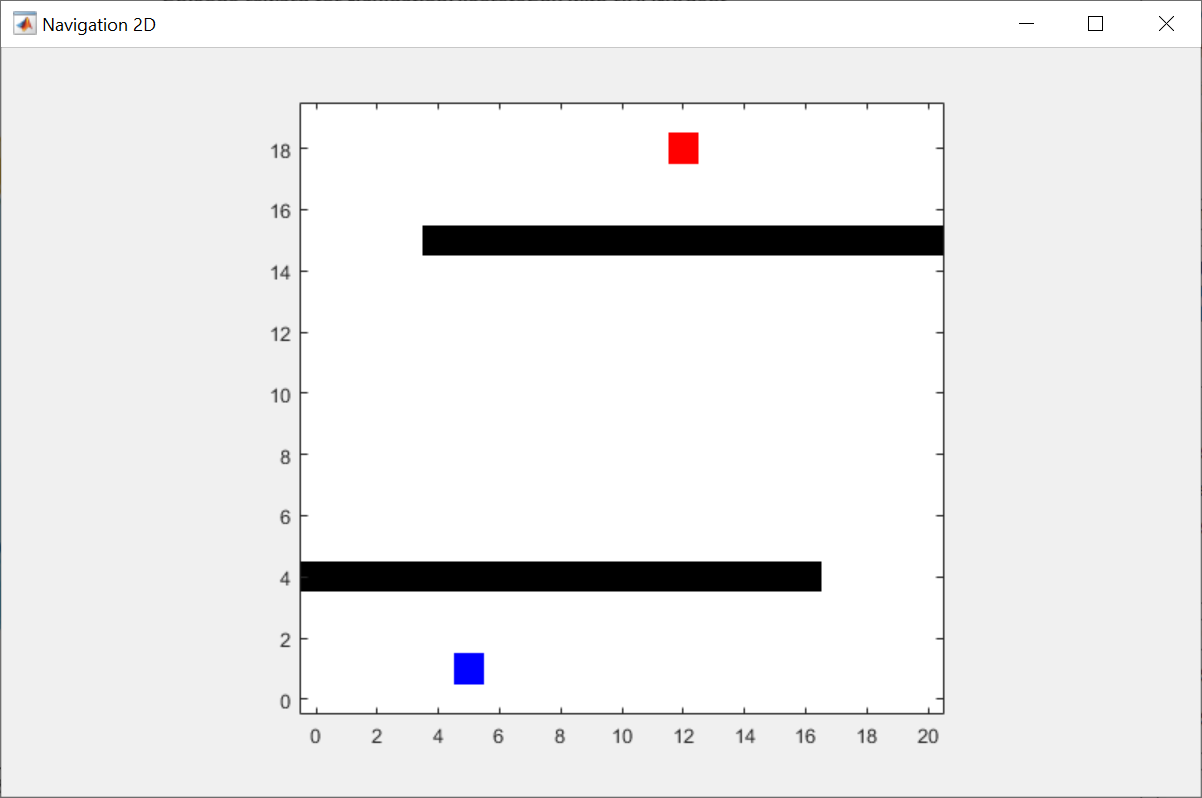 

The navigation problem in this example is a goal-conditioned task for which the observation from the environment contains both the goal (navigation target) and the goal measurement (robot position). The observation column vector contains the robot position $\left(x_{\textrm{robot}} ,y_{\textrm{robot}} \right)$  and the navigation target $\left(x_{\textrm{goal}} ,y_{\textrm{goal}} \right)$.


$$O={\left\lbrack x_{\textrm{robot}} ,y_{\textrm{robot}} ,x_{\textrm{goal}} ,y_{\textrm{goal}} \right\rbrack }^T$$
 

The initial position of the robot and the goal are sampled as follows:


$$\begin{array}{l}
x_{\mathrm{robot}} ~U\left\lbrace 0,19\right\rbrace \\
y_{\mathrm{robot}} ~U\left\lbrace 0,3\right\rbrace \\
x_{\mathrm{goal}} ~U\left\lbrace 0,19\right\rbrace \\
y_{\mathrm{goal}} ~U\left\lbrace 16,19\right\rbrace 
\end{array}$$


where $U\left\lbrace a,b\right\rbrace$ is a discrete uniform distribution between $a$ and $b$.

The discrete actions for this environment are defined as follows:


$$A=\left\lbrace \begin{array}{ll}
1 & y_{\textrm{robot}} =y_{\textrm{robot}} +1\;\;\;\;\left(\textrm{Go}\;\textrm{up}\right)\\
2 & y_{\textrm{robot}} =y_{\textrm{robot}} -1\;\;\;\;\left(\textrm{Go}\;\textrm{down}\right)\\
3 & x_{\textrm{robot}} =x_{\textrm{robot}} -1\;\;\;\;\left(\textrm{Go}\;\textrm{left}\right)\\
4 & x_{\textrm{robot}} =x_{\textrm{robot}} +1\;\;\;\;\left(\textrm{Go}\;\textrm{right}\right)
\end{array}\right.$$


If the action leads to the obstacle location or the map's boundary, the robot doesn't move.

The reward signal is defined as follows:


$$R=\left\lbrace \begin{array}{ll}
2 & \textrm{if}\;x_{\textrm{robot}} =x_{\textrm{goal}} \;\textrm{and}\;y_{\textrm{robot}} =y_{\textrm{goal}} \\
-0\ldotp 01-0\ldotp 01I\left(O,O^{\prime } \right) & \textrm{otherwise}
\end{array}\right.$$


where $O^{\prime } \;$is the next observation, and


$$I\left(O,O^{\prime } \right)=\left\lbrace \begin{array}{ll}
1 & \;\textrm{if}\;\textrm{the}\;\textrm{robot}\;{\textrm{doesn}}^{\prime } t\;\textrm{move}\;\textrm{due}\;\textrm{to}\;\textrm{obstacles}\;\textrm{or}\;\textrm{boundaries}\ldotp \\
0 & \textrm{otherwise}
\end{array}\right.$$
            

Terminal condition is defined as follows:


$$\mathrm{IsDone}=\left\lbrace \begin{array}{ll}
1 & \mathrm{if}\;x_{\mathrm{robot}} =x_{\mathrm{goal}} \;\mathrm{and}\;y_{\mathrm{robot}} =y_{\mathrm{goal}} \\
0 & \mathrm{otherwise}
\end{array}\right.$$


## Create Environment Interface

Fix the random generator seed for reproducibility.

rng(1)

Create a discrete navigation environment. `NavigationDiscreteEnv.m` is located in this example folder.

env = NavigationDiscreteEnv;

## Create DQN Agent

For a given observation and action, a DQN agent estimates the value of the policy (the cumulative discounted long-term reward) using a parametrized Q-value function critic.

Create a default DQN agent from the environment specifications. For more information `on` DQN agents, see [`rlDQNAgent`](docid:rl_ref#mw_167d0061-c095-446e-828f-816916a0f227).

obsInfo = getObservationInfo(env);
actInfo = getActionInfo(env);
agent = rlDQNAgent(obsInfo,actInfo);

Specify the DQN agent options, including training options for the critic. Alternatively, you can use [`rlDQNAgentOptions`](docid:rl_ref#mw_d66ae7b0-1964-4f66-a2ee-cfc08fc3657e) object.

agent.AgentOptions.EpsilonGreedyExploration.Epsilon = 1.0;
agent.AgentOptions.EpsilonGreedyExploration.EpsilonMin = 0.1;
agent.AgentOptions.EpsilonGreedyExploration.EpsilonDecay = 1e-5;
agent.AgentOptions.MiniBatchSize = 128;
agent.AgentOptions.CriticOptimizerOptions.LearnRate = 5e-4;
agent.AgentOptions.CriticOptimizerOptions.GradientThreshold = 1;

## Construct Hindsight Replay Memory

The DQN agent is unable to efficiently learn a good policy with a default replay memory because of the sparse rewards. You can improve the sample efficiency by using a hindsight replay memory for a goal-conditioned task with sparse rewards. The hindsight experience replay augments the acquired experiences by replacing the goal with the goal measurement so that agent can use the data that reaches the replaced goal. Thus, the agent can be trained with meaningful rewards even if the agent does not reach the goal. 

To use a hindsight replay memory, set `ExperienceBuffer` of the agent to `rlHindsightReplayMemory`. You need to specify the following.

- A reward function: The reward function, `myNavigationGoalRewardFcn`, computes the true reward given observation, action, and next observation. 

- An is-done function: The is-done function, `myNavigationGoalIsDoneFcn`, computes the true is-done signal given observation, action, and the next observation. 

- Goal condition information: `goalConditionInfo` specifies the channel and indices of goal measurements and goals. In this example, there is only one observation channel; the first and second observation elements correspond to the goal measurements (the robot position), and the third and fourth observation elements correspond to the goal position.

- Experience buffer length (optional): This examples uses 1e5. 

`myNavigationGoalRewardFcn.m` and `myNavigationGoalIsDoneFcn.m` are located in this example folder.  For more information, type `help rlHindsightReplayMemory`.

To use a standard replay memory, set `useHER `to `false`.

useHER = true;
if useHER    
    rewardFcn = @myNavigationGoalRewardFcn;
    isDoneFcn = @myNavigationGoalIsDoneFcn;
    % observation is [robot_x, robot_y, goal_x, goal_y]'
    % goal measurement: channel --- 1, indices --- 1,2
    % goal: channel --- 1, indices --- 3,4 
    goalConditionInfo = {{1,[2], 1, [3]}};
    bufferLength = 1e5;
    agent.ExperienceBuffer = rlHindsightReplayMemory(obsInfo,actInfo,...
        rewardFcn,isDoneFcn,goalConditionInfo,bufferLength);
else    
    agent.AgentOptions.ExperienceBufferLength = 1e5;
end

## Train Agent

To train the agent, first specify the training options. For this example, use the following options:

- Run one training session containing 3000 episodes, with each episode lasting at most 120 time steps.

- Display the training progress in the Reinforcement Learning Training Monitor dialog box (set the `Plots` option) and disable the command line display (set the `Verbose` option to `false`).

- Set the Plots options to "training-progress".

- Stop training when the agent receives an evaluation statistic (the mean value of evaluation episode rewards in this example) greater than 1.0.

For more information, see [`rlTrainingOptions`](docid:rl_ref#mw_1f5122fe-cb3a-4c27-8c80-1ce46c013bf0).

maxEpisodes = 3000;
maxStepsPerEpisode = 20;
trainOpts = rlTrainingOptions(...
    MaxEpisodes=maxEpisodes, ...
    MaxStepsPerEpisode=maxStepsPerEpisode, ...
    Verbose=false, ...
    ScoreAveragingWindowLength=100,...
    Plots="training-progress",...
    StopTrainingCriteria="EvaluationStatistic",...
    StopTrainingValue=2.0);

Use an `rlEvaluator` object to evaluate the agent periodically during training and to use the evaluation statistic for the stop training criteria. For this example, use the following options:

- Run 10 evaluation episodes at every every 50 training episodes.

- Use random seeds from 101 to 110 so that the same initial conditions can be used. For example, the first evaluation episode uses 101, and  the 10th evaluation episode uses 110.

- The evaluator uses the mean of the evaluation episode rewards as the default for "EvaluationStatisticType".

evaluator = rlEvaluator( ...
    EvaluationFrequency=50, ...
    NumEpisodes=10, ...
    RandomSeeds=101:110);

You can visualize the environment by using the `plot` function during training or simulation.

plot(env)

Train the agent using the [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function. Training this agent is a computationally intensive process. To save time while running this example, load a pretrained agent by setting `doTraining` to `false`. To train the agent yourself, set `doTraining` to `true`.

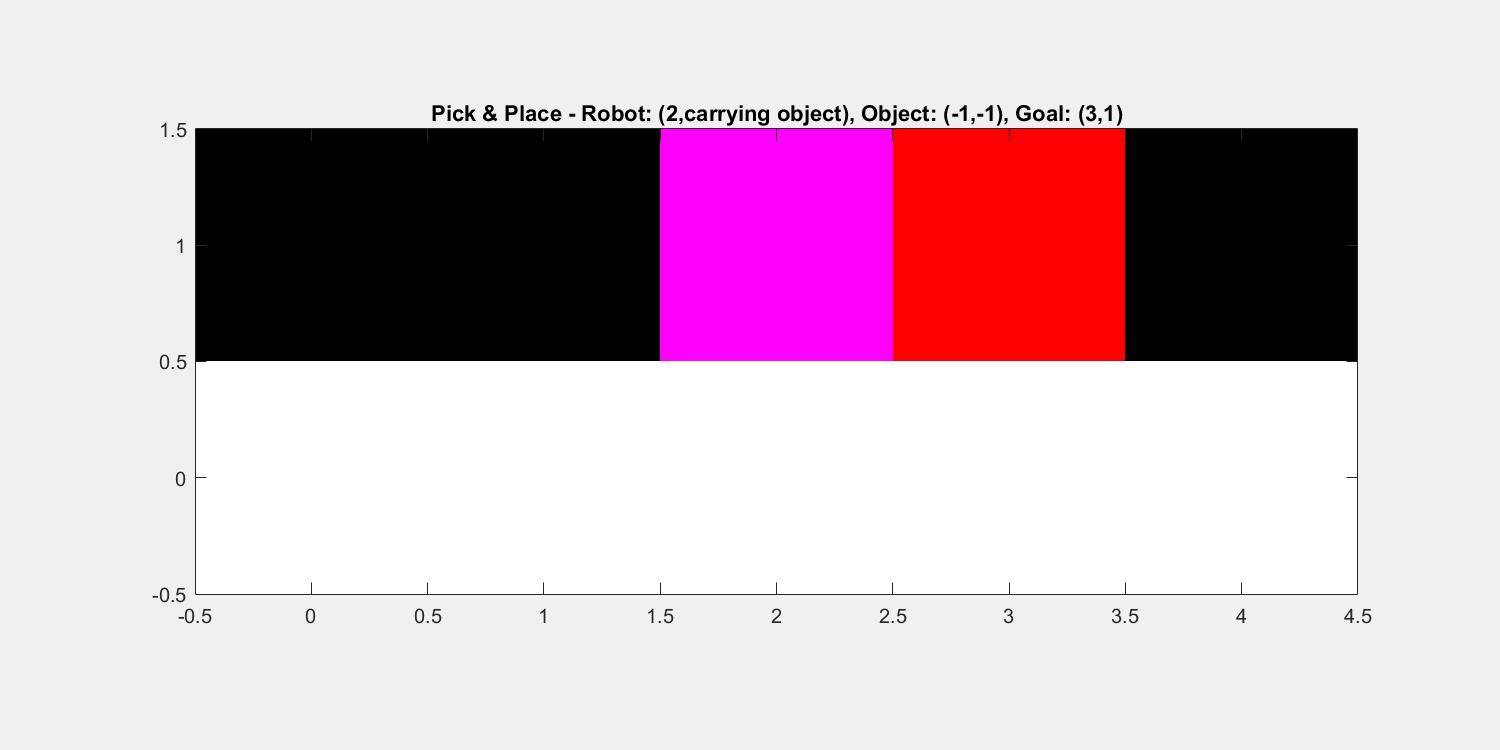

doTraining = true;
if doTraining
    % Train the agent.    
    env.disableVisualization();
    trainingStats = train(agent,env,trainOpts, Evaluator=evaluator);
else
    % Load the pretrained agent for the example.
    load("DiscreteNavigationDQNAgent.mat","agent")
end

The following figure shows a snapshot of training progress.

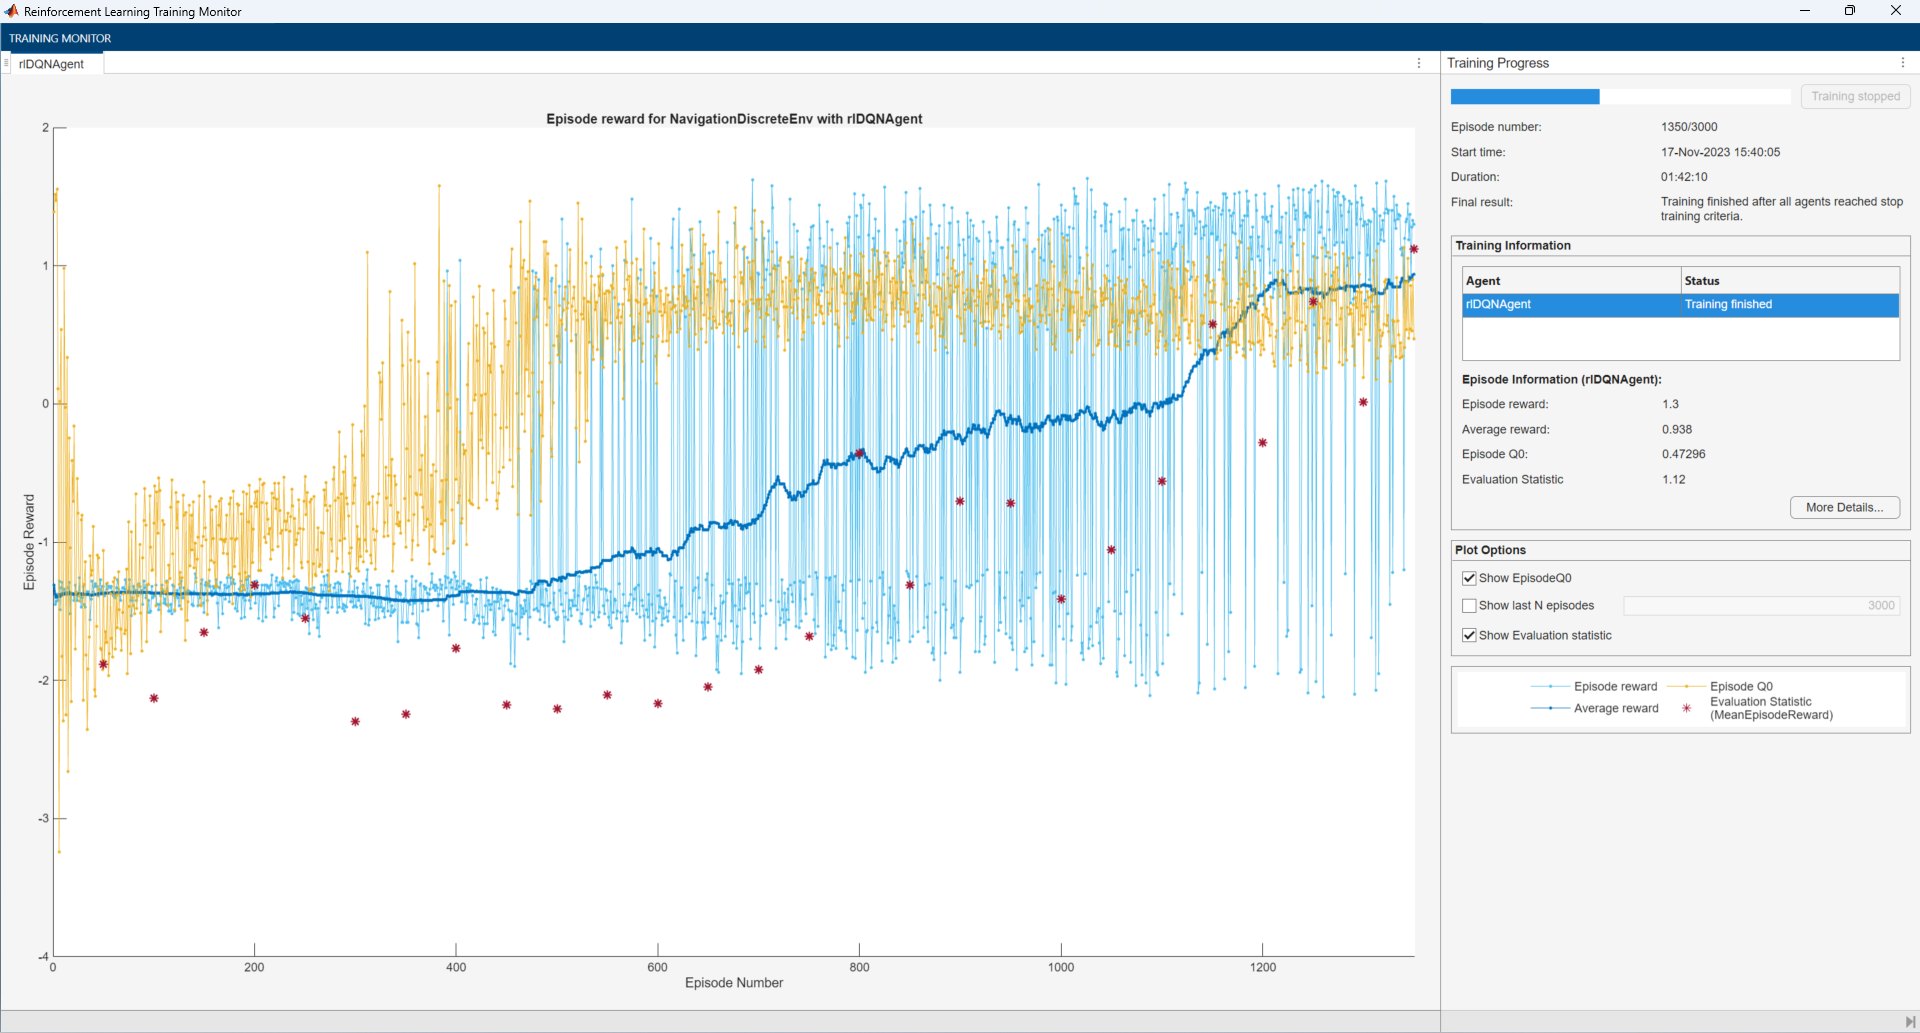

## Simulate DQN Agent

Since the reset function randomizes the reference values, fix the random generator seed to ensure simulation reproducibility.

rng(230)

To validate the performance of the trained agent, simulate it within the navigation environment. For more information on agent simulation, see [`rlSimulationOptions`](docid:rl_ref#mw_983bb2e9-0115-4548-8daa-687037e090b2) and [`sim`](docid:rl_ref#mw_e6296379-23b5-4819-a13b-210681e153bf). 

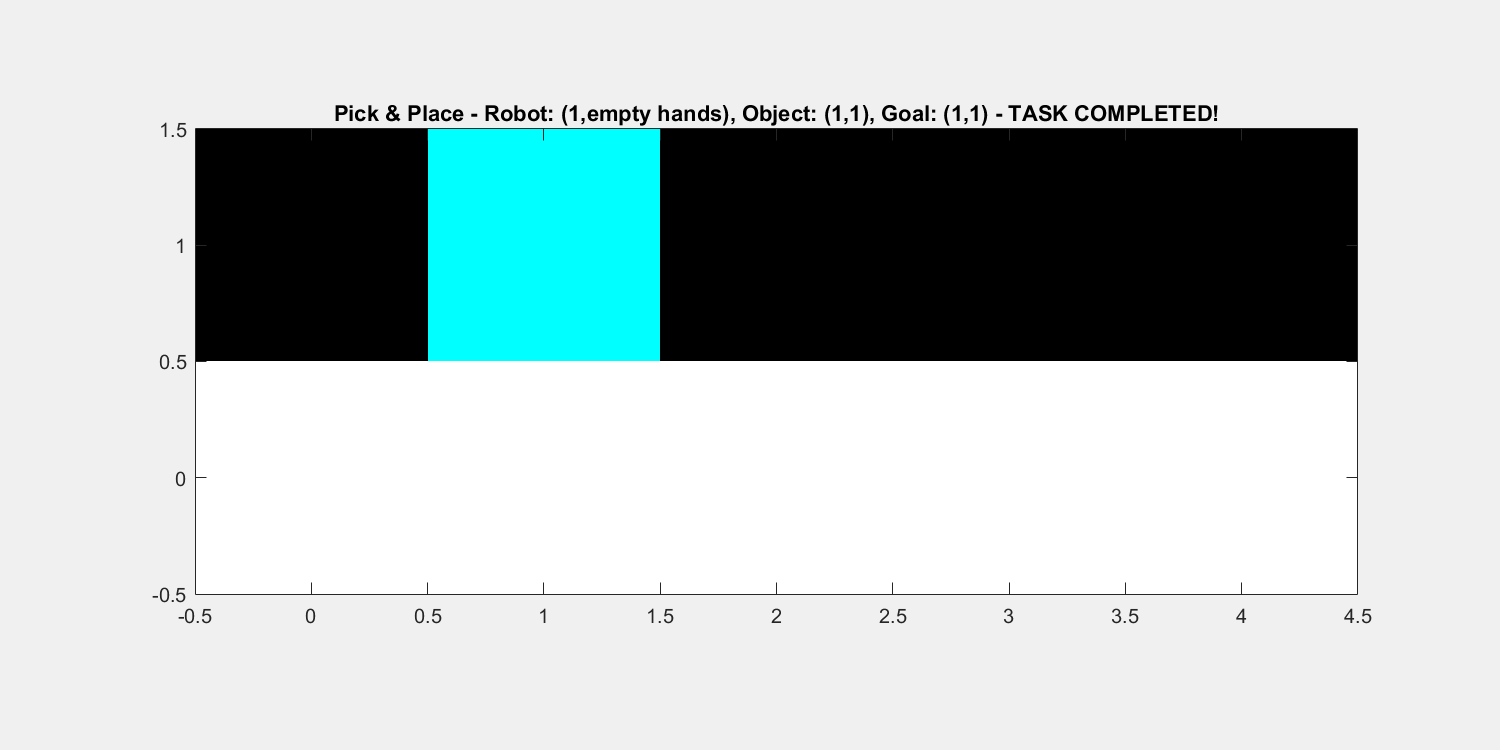

env.enableVisualization()
plot(env)
simOptions = rlSimulationOptions(...
    NumSimulations=1,...
    MaxSteps=maxStepsPerEpisode);
simResults = sim(env,agent,simOptions);

The trained agent successfully reached the goal. 

save('miAgenteDQN_HER.mat', 'agent');


load('miAgenteDQN_HER.mat', 'agent');

## Reference

Andrychowicz, Marcin, Filip Wolski, Alex Ray, Jonas Schneider, Rachel Fong, Peter Welinder, Bob McGrew, Josh Tobin, Pieter Abbeel, and Wojciech Zaremba. "Hindsight experience replay." *Advances in neural information processing systems* 30 (2017).

*Copyright 2023 The MathWorks, Inc.*